В этом разделе производится загрузка метаданных и формирование подмножеств данных на основе заданных условий. Данные содержатся в каталоге DataSet/Faulty bearing. Функция collectMetadata загружает метаинформацию обо всех доступных файлах в указанной директории. Эта метаинформация используется для фильтрации и выбора нужных файлов с токовыми сигналами.

Формируются датасеты для разных частот (10, 20, 30 и 40 Гц) для двигателя в режиме холостого хода и для нагрузки.

dataset5 - холостой ход, все частоты

dataset9 - под нагрузкой, все частоты

dataset10 - все файлы

clear
rootDir = 'DataSet/Faulty bearing';

% Load metadata
dataTable = collectMetadata(rootDir);

% Form datasets
% 10 Hz sistem HH
dataset1 = selectFiles(dataTable, {"frequency converter №2", "serviceable bearing"}, ...
    "sistem HH", "10hz", "Current");
dataset1 = [dataset1; selectFiles(dataTable, "misalignment", "HH", "10hz", "Current")];
% 20 Hz sistem HH
dataset2 = selectFiles(dataTable, {"frequency converter №2", "serviceable bearing"}, ...
    "sistem HH", "20hz", "Current");
dataset2 = [dataset2; selectFiles(dataTable, "misalignment", "HH", "20hz", "Current")];
% 30 Hz sistem HH
dataset3 = selectFiles(dataTable, {"frequency converter №2", "serviceable bearing"}, ...
    "sistem HH", "30hz", "Current");
dataset3 = [dataset3; selectFiles(dataTable, "misalignment", "HH", "30hz", "Current")];
% 40 Hz sistem HH
dataset4 = selectFiles(dataTable, {"frequency converter №2", "serviceable bearing"}, ...
    "sistem HH", "40hz", "Current");
dataset4 = [dataset4; selectFiles(dataTable, "misalignment", "HH", "40hz", "Current")];

% XX Hz sistem HH
dataset5 = [dataset1; dataset2; dataset3; dataset4];

% 20 Hz sistem HH + brake
dataset6 = selectFiles(dataTable, {"frequency converter №2", "serviceable bearing"}, ...
    "sistem HH + brake", "20hz", "Current");
dataset6 = [dataset6; selectFiles(dataTable, "misalignment", "under load", "20hz", "Current")];
% 30 Hz sistem HH + brake
dataset7 = selectFiles(dataTable, {"frequency converter №2", "serviceable bearing"}, ...
    "sistem HH + brake", "30hz", "Current");
dataset7 = [dataset7; selectFiles(dataTable, "misalignment", "under load", "30hz", "Current")];
% 40 Hz sistem HH + brake
dataset8 = selectFiles(dataTable, {"frequency converter №2", "serviceable bearing"}, ...
    "sistem HH + brake", "40hz", "Current");
dataset8 = [dataset8; selectFiles(dataTable, "misalignment", "under load", "40hz", "Current")];

% XX Hz sistem HH + Brake
dataset9 = [dataset6; dataset7; dataset8];

% XX Hz XX
dataset10 = [dataset5; dataset9];

% Current Dataset
files = dataset5;

На этом этапе разбиваем каждый сигнал тока на перекрывающиеся окна фиксированной длины, очищаем данные от выбросов, извлекаем численные признаки и формируем обучающую выборку для последующего анализа. Используем **окна по 1 секунде** с **перекрытием 50%**, что позволяет получить больше примеров и повысить стабильность признаков. Размер окна в отсчётах:


$$[
\text{windowSize} = F_s \cdot t = 10000 \cdot 1 = 10000 \text{ отсчётов}
]$$



$$[
\text{stepSize} = \frac{\text{windowSize}}{2} = 5000 \text{ отсчётов}
]$$


**Извлечение признаков:**

Функция **extractCurrentFeaturesTable** возвращает:

- *fArray* — массив признаков (вектор чисел)

- *fTable* — таблицу с именованными признаками (для отладки и визуализации)

Для каждого окна сигнала извлекается множество признаков, описывающих его поведение во **временной** и **частотной областях**. Также учитываются **взаимосвязи между фазами**.

Сигнал имеет две компоненты (фаза A и фаза B). Признаки извлекаются для каждой фазы отдельно и дополняются совместными характеристиками.

#### ***Временные признаки (для каждой фазы):***

**Среднее значение (Mean)**


$$[\mu = \frac{1}{N} \sum_{i=1}^N x_i]$$


**Стандартное отклонение (Std)**


$$[\sigma = \sqrt{ \frac{1}{N-1} \sum_{i=1}^N (x_i - \mu)^2 }]$$


**Среднеквадратичное значение (RMS)**


$$[\text{RMS} = \sqrt{ \frac{1}{N} \sum_{i=1}^N x_i^2 }]$$


**Асимметрия (Skewness)**


$$[\text{Skew} = \frac{1}{N} \sum_{i=1}^N \left( \frac{x_i - \mu}{\sigma} \right)^3]$$


**Эксцесс (Kurtosis)**


$$[\text{Kurt} = \frac{1}{N} \sum_{i=1}^N \left( \frac{x_i - \mu}{\sigma} \right)^4]$$


**Размах (Peak-to-Peak)**


$$[\text{P2P} = \max(x) - \min(x)]$$


**Крест-фактор (Crest Factor)**


$$[\text{CF} = \frac{\max |x_i|}{\text{RMS}}]$$


#### ***Частотные признаки (для каждой фазы):***

**Основная частота (Dominant Frequency) **Частота, соответствующая максимуму спектральной амплитуды:


$$[f_{\text{peak}} = \arg\max |X_k|]$$


**Спектральная энергия (Spectral Energy) **


$$[E = \sum_{k} |X_k|^2]$$


**Спектральный центроид (Spectral Centroid)**


$$[C = \frac{ \sum f_k \cdot |X_k| }{ \sum |X_k| }]$$


**Спектральная энтропия (Spectral Entropy)**


$$[H = -\sum p_k \cdot \log_2(p_k), \quad p_k = \frac{|X_k|}{\sum |X_k|}]$$


#### ***Кросс-фазные признаки (между фазами A и B):***

**Коэффициент корреляции (Correlation A↔B)**


$$[\rho = \frac{\text{cov}(x_A, x_B)}{\sigma_A \cdot \sigma_B}]$$


**Векторное RMS (Vector RMS)**


$$[\text{RMS}{\text{vec}} = \frac{1}{N} \sum{i=1}^N \sqrt{ x_{A,i}^2 + x_{B,i}^2 }]$$


На выходе имеем:

- *X* — числовая матрица признаков (для обучения модели)

- *Y* — метки классов (строки)

- featureTables — подробная таблица с признаками, временем окна, индексом файла и меткой неисправности. 

Fs = 10000;
windowDuration = 1;  % seconds
windowSize = Fs * windowDuration;  % samples
stepSize = windowSize / 2;  % 50% overlap

X = [];
featureTables = table();  % For debugging/inspection
Y = {};

for i = 1:height(files)
    filePath = files.FilePath{i};
    faultLabel = files.Fault{i}; 

    [data, ~] = readCurrentSignal(filePath, 2, Fs);
    N = size(data, 1);

    for startIdx = 1:stepSize:(N - windowSize + 1)
        stopIdx = startIdx + windowSize - 1;
        window = data(startIdx:stopIdx, :);
        
        % === Remove outliers === 
        window = filloutliers(window,"linear","movmedian",400);

        % Extract features
        [fArray, fTable] = extractCurrentFeaturesTable(window, Fs);

        % === Add debug info ===
        % Time interval string (e.g., "0.00 - 1.00 s")
        tStart = (startIdx - 1) / Fs;
        tEnd = (stopIdx - 1) / Fs;
        fTable.TimeInterval = string(sprintf('%.2f - %.2f s', tStart, tEnd));
        fTable.FileIndex = i;
        fTable.FaultLabel = string(faultLabel);

        % Reorder columns to put debug info first
        debugCols = ["TimeInterval", "FileIndex", "FaultLabel"];
        allCols = fTable.Properties.VariableNames;
        newColOrder = [debugCols, allCols(~ismember(allCols, debugCols))];
        fTable = fTable(:, newColOrder);

        % Store
        X = [X; fArray];
        featureTables = [featureTables; fTable];
        Y{end+1,1} = faultLabel;  % Use as class label
    end
end

% Remove some features to test
featuresExcluded = ["Mean_A", "Mean_B"];
excludeIdx = find(ismember(string(featureTables.Properties.VariableNames), featuresExcluded));
excludeIdx = excludeIdx - 3;
X(:, excludeIdx) = [];

После извлечения признаков и формирования меток классов, необходимо подготовить обучающую и тестовую выборки.

Метки классов конвертируются в тип categorical, чтобы их можно было использовать в моделях классификации.

Вместо случайного разбиения отдельных окон (что может привести к **утечке информации** между обучающей и тестовой выборками), мы делим данные по **файлам**, то есть по источникам сигналов. Это имитирует реальную ситуацию, когда модель должна обобщать на **новые файлы**, а не просто на новые окна из тех же файлов.

Модель TreeBagger используется для построения ансамбля деревьев решений. 

- TreesNum = 100 — количество деревьев в ансамбле

% Convert Y to categorical
Y = categorical(Y);

% Split dataset by windows
% rng(42);
% cv = cvpartition(Y, 'HoldOut', 0.2);  % 80% train, 20% test
% XTrain = X(cv.training, :);
% YTrain = Y(cv.training);
% XTest = X(cv.test, :);
% YTest = Y(cv.test);

% Split dataset by files
[isTrain, isTest, trainFiles, testFiles] = equalFileSplit(featureTables.FileIndex, Y, 0.2);
XTrain = X(isTrain, :);
YTrain = Y(isTrain);
XTest  = X(isTest, :);
YTest  = Y(isTest);

% Train Random Forest
TreesNum = 100;
RFModel = TreeBagger(TreesNum, XTrain, YTrain, ...
    'OOBPrediction', 'on', ...
    'OOBPredictorImportance', 'on');

После обучения модели случайного леса (TreeBagger) мы можем оценить её качество без использования тестовой выборки, с помощью **OOB-ошибки** (*Out-of-Bag Error*).

Это встроенная функция случайного леса, которая проверяет, насколько хорошо модель предсказывает примеры, **не попавшие в обучающую подвыборку каждого дерева**.

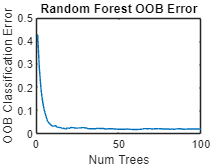

% View OOB error
figure;
oobErrorBaggedEnsemble = oobError(RFModel);
plot(oobErrorBaggedEnsemble);
xlabel('Num Trees');
ylabel('OOB Classification Error');
title('Random Forest OOB Error');

После применения обученной модели к тестовой выборке мы визуализируем результаты классификации с помощью **confusion chart** (матрицы ошибок). Это наглядный способ оценить, какие классы модель предсказывает правильно, а какие — путает между собой.

- **Главная диагональ** показывает количество правильно классифицированных примеров

- **Вне диагонали** — ошибки классификации

- Чем **ярче диагональ** и **темнее остальное** — тем лучше модель

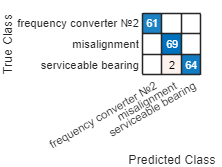

% Confusion Chart
YPredTest = categorical(predict(RFModel, XTest));
confusionchart(YTest, YPredTest);

После обучения модели случайного леса (TreeBagger) можно оценить, какие признаки наиболее сильно повлияли на результат классификации. Мы используем метрику **OOB Permuted Predictor Importance** — изменение ошибки при случайной перестановке значений конкретного признака (*permutation importance*).

- Признаки сортируются по убыванию важности

- Таким образом, первые в списке — самые значимые

- Гистограмма визуализирует, какие признаки наиболее важны

- Ось X: имена признаков

- Ось Y: значение важности (чем выше — тем важнее)

- **Важные признаки** — те, при перестановке которых ошибка модели заметно возрастает

- **Неважные признаки** — те, перестановка которых почти не влияет на результат

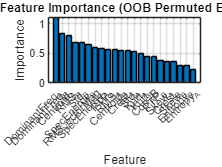

% Feature Importance Analysis
imp = RFModel.OOBPermutedPredictorDeltaError;
% Get feature names from table (excluding debug columns)
allNames = featureTables.Properties.VariableNames;
debug_exclude = ["TimeInterval", "FileIndex", "FaultLabel"];
featureNames = allNames(~ismember(allNames, debug_exclude));
featureNames = featureNames(~ismember(featureNames, featuresExcluded));

% Sort importance features
[sortedImportance, sortIdx] = sort(imp, 'descend');
sortedFeatureNames = featureNames(sortIdx);

% Plot
figure;
bar(sortedImportance);
title('Feature Importance (OOB Permuted Error)');
xlabel('Feature');
ylabel('Importance');
xticks(1:length(sortedFeatureNames));
xticklabels(sortedFeatureNames);
xtickangle(45);  % Rotate labels for readability
grid on;

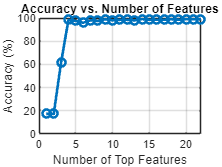

% Accuracy, F1, Precision, recall vs number of features
maxFeatures = length(sortIdx);
accuracies = zeros(maxFeatures, 1);
precisions = zeros(maxFeatures, 1);
recalls    = zeros(maxFeatures, 1);
f1scores   = zeros(maxFeatures, 1);

for N = 1:maxFeatures
    idx = sortIdx(1:N);

    XTrainSub = XTrain(:, idx);
    XTestSub  = XTest(:, idx);

    model = TreeBagger(TreesNum, XTrainSub, YTrain);

    % Predict
    YPred = categorical(predict(model, XTestSub));

    % === Metrics ===
    % Confusion matrix
    conf = confusionmat(YTest, YPred);

    % Support multiple classes
    TP = diag(conf);
    FP = sum(conf, 1)' - TP;
    FN = sum(conf, 2) - TP;
    TN = sum(conf(:)) - (TP + FP + FN);

    % Per-class metrics
    precision = TP ./ (TP + FP + eps);
    recall    = TP ./ (TP + FN + eps);
    f1        = 2 * (precision .* recall) ./ (precision + recall + eps);

    % Average (macro) metrics
    precisions(N) = mean(precision);
    recalls(N)    = mean(recall);
    f1scores(N)   = mean(f1);
    accuracies(N) = mean(YPred == YTest);
end

% === METRICS DISPLAY ===
figure;
plot(1:maxFeatures, accuracies * 100, '-o', 'LineWidth', 2);
ylabel('Accuracy (%)');
xlabel('Number of Top Features');
title('Accuracy vs. Number of Features');
grid on;

[~, bestN] = max(accuracies);
bestFeatures = sortedFeatureNames(1:bestN);
fprintf('Best accuracy: %.4f with %d features\n', accuracies(bestN), bestN);

Best accuracy: 0.9898 with 9 features


fprintf('Features used:\n');

Features used:


disp(bestFeatures');

    {'DominantFreq_A'}
    {'DominantFreq_B'}
    {'Centroid_A'    }
    {'RMS_B'         }
    {'Std_B'         }
    {'SpecEnergy_B'  }
    {'RMS_VectorMag' }
    {'SpecEnergy_A'  }
    {'PTP_A'         }



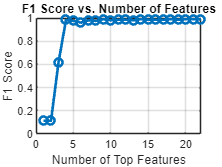


figure;
plot(1:maxFeatures, f1scores, '-o', 'LineWidth', 2);
ylabel('F1 Score');
xlabel('Number of Top Features');
title('F1 Score vs. Number of Features');
grid on;

[~, bestN] = max(f1scores);
bestFeatures = sortedFeatureNames(1:bestN);
fprintf('Best F1 Score: %.4f with %d features\n', f1scores(bestN), bestN);

Best F1 Score: 0.9901 with 9 features


fprintf('Features used:\n');

Features used:


disp(bestFeatures');

    {'DominantFreq_A'}
    {'DominantFreq_B'}
    {'Centroid_A'    }
    {'RMS_B'         }
    {'Std_B'         }
    {'SpecEnergy_B'  }
    {'RMS_VectorMag' }
    {'SpecEnergy_A'  }
    {'PTP_A'         }



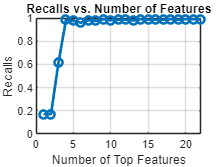


figure;
plot(1:maxFeatures, recalls, '-o', 'LineWidth', 2);
ylabel('Recalls');
xlabel('Number of Top Features');
title('Recalls vs. Number of Features');
grid on;

[~, bestN] = max(recalls);
bestFeatures = sortedFeatureNames(1:bestN);
fprintf('Best recall: %.4f with %d features\n', recalls(bestN), bestN);

Best recall: 0.9899 with 9 features


fprintf('Features used:\n');

Features used:


disp(bestFeatures');

    {'DominantFreq_A'}
    {'DominantFreq_B'}
    {'Centroid_A'    }
    {'RMS_B'         }
    {'Std_B'         }
    {'SpecEnergy_B'  }
    {'RMS_VectorMag' }
    {'SpecEnergy_A'  }
    {'PTP_A'         }



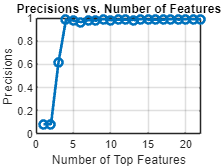


figure;
plot(1:maxFeatures, precisions, '-o', 'LineWidth', 2);
ylabel('Precisions');
xlabel('Number of Top Features');
title('Precisions vs. Number of Features');
grid on;

[~, bestN] = max(precisions);
bestFeatures = sortedFeatureNames(1:bestN);
fprintf('Best precision: %.4f with %d features\n', precisions(bestN), bestN);

Best precision: 0.9906 with 9 features


fprintf('Features used:\n');

Features used:


disp(bestFeatures');

    {'DominantFreq_A'}
    {'DominantFreq_B'}
    {'Centroid_A'    }
    {'RMS_B'         }
    {'Std_B'         }
    {'SpecEnergy_B'  }
    {'RMS_VectorMag' }
    {'SpecEnergy_A'  }
    {'PTP_A'         }

